C = @(m,n) factorial(n)/(factorial(n-m)*factorial(m));
A = @(m,n) factorial(n)/factorial(n-m);
P = @(n) factorial(n);

Задача №1

На оптовой базе имеются изделия трёх сортов: 22 изделий первого сорта, 28 второго, 20 третьего.

Найти:

а) относительную частоту изделий первого сорта;

б) вероятность того, что все 9 выбранных изделий  будут первого сорта;

в) вероятность того, что среди 9 выбранных изделий будет 2 первого сорта;

г) вероятность того, что среди 9 выбранных изделий будет 2 первого сорта, 4 второго, 3 третьего;

д) вероятность того, что среди 9 выбранных изделий будет хотя бы одно первого сорта.

Решение:

n=70;
n1=22;
n2=28;
n3=20;
m=9;
m1=2;
m2=4;
m3=3;

а) относительную частоту изделий первого сорта;

P_A = n1/n

P_A = 0.3143

б) вероятность того, что все 9 выбранных изделий  будут первого сорта;

P_A = C(m,n1)/C(m,n)

P_A = 7.6487e-06

в) вероятность того, что среди 9 выбранных изделий будет 2 первого сорта;

P_A = C(m1,n1)*C(m-m1,n-n1)/C(m,n)

P_A = 0.2615

г) вероятность того, что среди 9 выбранных изделий будет 2 первого сорта, 4 второго, 3 третьего;

P_A = C(m1,n1)*C(m2,n2)*C(m3,n3)/C(m,n)

P_A = 0.0829

д) вероятность того, что среди 9 выбранных изделий будет хотя бы одно первого сорта.

P_A = 1-C(m,n-n1)/C(m,n)

P_A = 0.9742

Задача №2

    Три орудия стреляют в цель независимо друг от друга. Вероятность попадания в цель 0.5; 0.7;0.9 соответственно для первого, второго и третьего орудия. Найти вероятность того, что: 

а) все триорудия попадут в цель;

б) попадёт только одно;

в) попадут два, однопромахнётся;

г) попадёт хотя бы одно.

Решение:

p1=0.5;
p2=0.7;
p3=0.9;

а) все три орудия попадут в цель;

P_A = p1*p2*p3

P_A = 0.3150

б) попадёт только одно;

P_A = (p1*(1-p2)*(1-p3))+((1-p1)*p2*(1-p3))+((1-p1)*(1-p2)*p3)

P_A = 0.1850

в) попадут два, одно промахнётся;

P_A = ((1-p1)*p2*p3)+(p1*(1-p2)*p3)+(p1*p2*(1-p3))

P_A = 0.4850

г) попадёт хотя бы одно.

P_A = 1-((1-p1)*(1-p2)*(1-p3))

P_A = 0.9850

Задача №3

На склад поступило три партии ламп. В первой партии 120 ламп, во второй 380, в третьей 500. В первой партии 

10% бракованных ламп, во второй 6%, в третьей 9%. Требуется:

а)  найти  вероятность  того,  что  наудачу  выбранная  лампа  будет бракованной;

б) наудачу выбранная лампа оказалась бракованной. Найти вероятность того, что она из 2 партии.

Решение:

n=1000;
n1=120;
n2=380;
n3=n-120-380;
m1=0.10;
m2=0.06;
m3=0.09;
i=2;

а)  найти  вероятность  того,  что  наудачу  выбранная  лампа  будет бракованной;

P_A = n1/n*m1+n2/n*m2+n3/n*m3

P_A = 0.0798

б) наудачу выбранная лампа оказалась бракованной. Найти вероятность того, что она из 2 партии.

P_A = (n1/n*m1)/(n1/n*m1+n2/n*m2+n3/n*m3)

P_A = 0.1504

Задача №4

Вероятность  появления  события Ав  каждом испытанииравна р. 

Найти вероятность того, что вnиспытаниях событие А появится: 

а) ровно k1 раз;

б) не менее k1 раз;

в) не более k2 раз;

г) хотя бы один раз (для нечётных вариантов, где n=10);

д) от k1 до k2 раз (для чётных вариантов, где n=100).

n=10;
k1=6;
k2=8;
p=0.7;
P = @(k) C(k,n)*p^k*(1-p)^(n-k);

а) ровно k1 раз;

P_A = P(k1) 

P_A = 0.2001

б) не менее k1 раз;

P_A = 0;
for n=k1:n
    P_A = P_A+P(n);
end
P_A

P_A = 0.8497

в) не более k2 раз;

P_A = 0;
for n=0:k1
    P_A = P_A+P(n);
end
P_A

P_A = 0.3504

г) хотя бы один раз (для нечётных вариантов, где n=10);

P_A = 1-P(0)

P_A = 1.0000

Задача №5

Дискретная случайная величина Х задана рядом распределения

Найти:

а) функцию распределения F(x), построить график F(x);

б)  математическое  ожидание,  дисперсию,  среднее  квадратическое отклонение, моду;

в) вероятность попадания Х в интервал (0;7).

Решение:

X = [1 2 4 5 6 8];
P = [0.3 0.14 0.16 0.03 0.2 0.17];
a = 0;
b = 7;

а) функцию распределения F(x), построить график F(x);

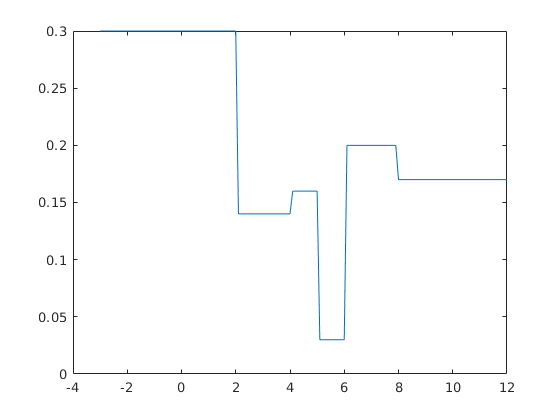

plot(X(1)-4:.1:X(length(X))+4,F5(X(1)-4:.1:X(length(X))+4,X,P))

б)  математическое  ожидание,  дисперсию,  среднее  квадратическое отклонение, моду;

M5(X,P)

ans = 3.9300

D_X = M5((X-M5(X,P)).^2,P)

D_X = 6.8051

d_x = sqrt( M5((X-M5(X,P)).^2,P) )

d_x = 2.6087

в) вероятность попадания Х в интервал (0;7).

P_a_b = abs(F5(b,X,P)-F5(a,X,P))

P_a_b = 0.1000

Задача №6

Непрерывная случайная величина Х задана плотностью распределения

Найти:

а)функцию распределения F(x); 

б)  математическое  ожидание,  дисперсию,  среднее  квадратическое отклонение, моду, медиану;

в) вероятность попадания Хв интервал (0;1).Построить графики F(x) и f(x).

Решение:

a=0;
b=1;

а)функцию распределения F(x); 

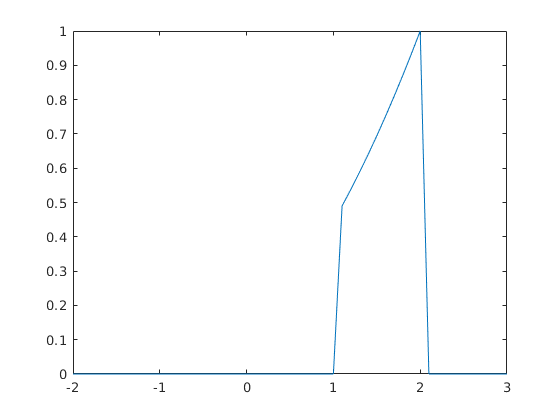

plot(-2:.1:3,F6(-2:.1:3))

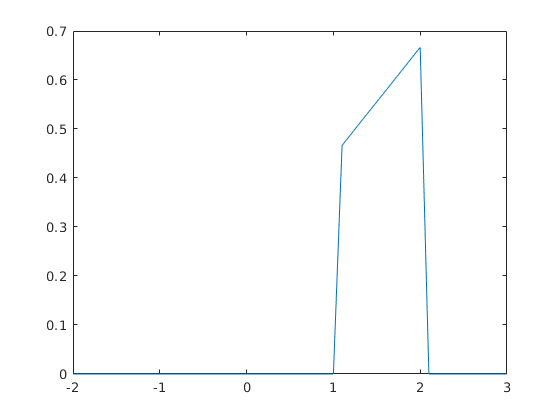

plot(-2:.1:3,F6_diff(-2:.1:3))

б)  математическое  ожидание,  дисперсию,  среднее  квадратическое отклонение, моду, медиану;

в) вероятность попадания Хв интервал (0;1).Построить графики F(x) и f(x).

Функции:

5

function sum = M5(X,P)
    sum=0;
    for n=1:length(X)
        sum=sum+X(n)*P(n);
    end
end
function [ans] = F5(var,X,P)
    for varn = 1:length(var)
       if var(varn)<=X(1)
            ans(varn) = P(1);
        elseif var(varn)>=X(length(X))
            ans(varn) = P(length(X));
        else
            for n=1:length(X)-1
                if X(n)<var(varn) && var(varn)<=X(n+1)
                    ans(varn) = P(n);
                end
            end 
        end 
    end
end

6

function [ans] = F6_diff(var)
    for varn=1:length(var)
        if var(varn)<=1 || var(varn)>2
            ans(varn) = 0;
        elseif var(varn)>-1 && var(varn)<=2
            syms x;
            ans(varn) = vpa(subs(diff(1/9*(x+1)^2),x,var(varn)));
        end 
    end 
end
function [ans] = F6(var)
for varn=1:length(var)
    if var(varn)<=1 || var(varn)>2
        ans(varn) = 0;
    elseif var(varn)>-1 && var(varn)<=2
        ans(varn) = 1/9*(var(varn)+1)^2;
    end 
end 
end